h = 0.1;
domain = Domain('square');
mesh = Mesh(domain,h);

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0.3 s)


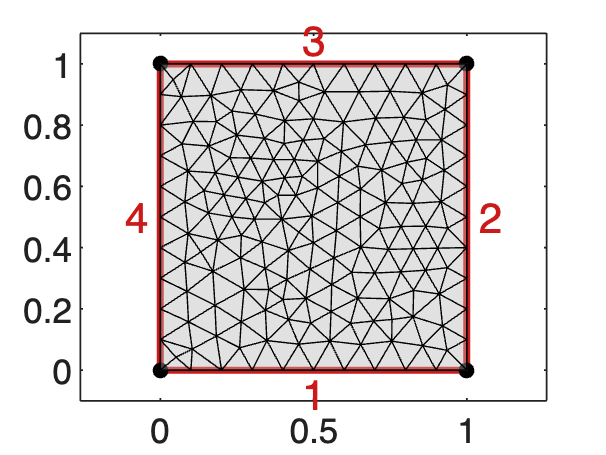

domain.plot('edgelabels');
hold on
mesh.plot

%Calcul qualité maillage

P=mesh.nodes;
qual=1;
T=mesh.triangles;
for i = 1:size(T,1)
    p1 = P(T(i,1), :);
    p2 = P(T(i,2), :);
    p3 = P(T(i,3), :);
    [s,d,q] = geo(p1,p2,p3);
    if q<qual
        qual=q;
    end
end
disp(qual)

    0.4265



%q=0.4265

M=matriceM(P,T);
K=matriceK(P,T);
test_matrice(mesh,K)

ans = logical
   1


test_matrice(mesh,M)

ans = logical
   1


%Les matrices M et K calculées sont valides

%Q.4 Par calcul intégral, la norme L2 de f vaut 1/2. La norme H1 de f vaut
%sqrt(1+2*pi^2)/2

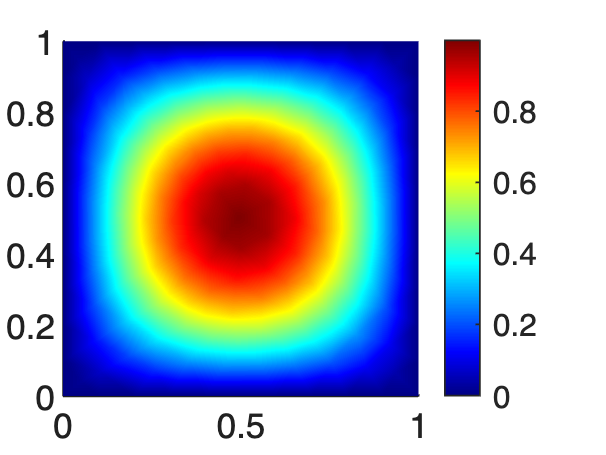

NN = size(P, 1);
fh=sin(pi*P(:,1)).*sin(pi*P(:,2));

figure;
mesh.image(fh);

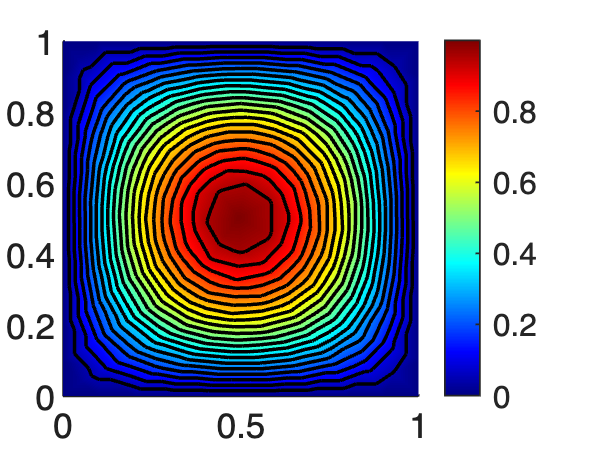

figure;
mesh.contourf(fh);

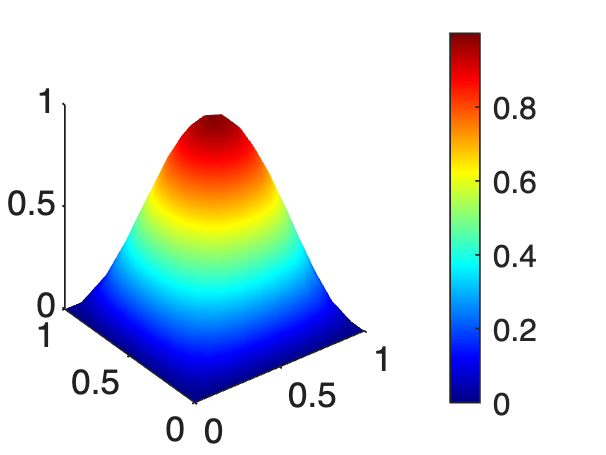

figure;
mesh.surf(fh);

%Q6
H=[0.025 0.05 0.075 0.1];
ec_L2=zeros(1,4);
ec_H1=zeros(1,4);
for i=1:4 
    domain = Domain('square') ;
    mesh = Mesh(domain,H(i)) ;
    P = mesh.nodes;
    T = mesh.triangles;

    % Interpolation de f sur Vh
    NN = size(P, 1);
    fh=sin(pi*P(:,1)).*sin(pi*P(:,2));

    K = matriceK(P, T);
    M = matriceM(P, T);
    ec_L2(1,i)=abs(normL2(fh,M)-1/2);
    ec_H1(1,i)=abs(normH1(fh,M,K)-sqrt(1+2*pi^2)/2);
end

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (5492 triangles, 0.4 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (1338 triangles, 0.1 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (596 triangles, 0 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0.1 s)


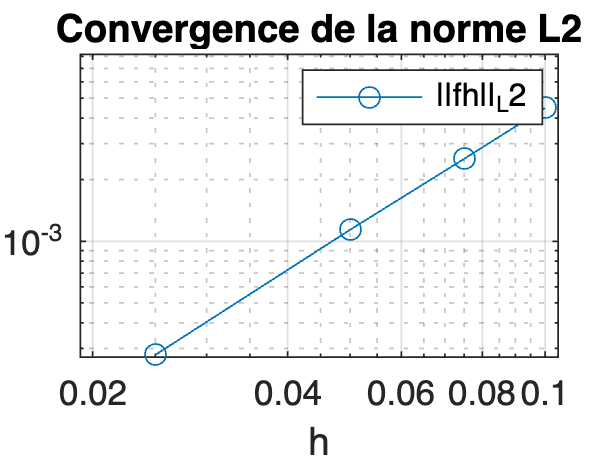

% Figure 1 — Norme L2
figure;
loglog(H, ec_L2, '-o', DisplayName='||fh||_L2');
xlabel('h'); legend; grid on;
title('Convergence de la norme L2');

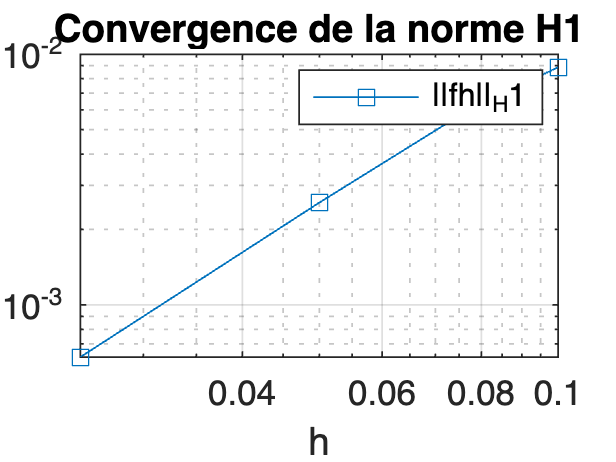


% Figure 2 — Norme H1
figure;
loglog(H, ec_H1, '-s', DisplayName='||fh||_H1');
xlabel('h'); legend; grid on;
title('Convergence de la norme H1');

%Ordres de convergence